# P2. Dinámica Lateral del Vehículo

Sistemas de Control de Vehículos

Grado en Ingeniería Electrónica, Robótica y Mecátronica

Universidad de Málaga

Creado por: David Rodríguez Martínez

Última actualización: 28 Septiembre 2026

### Introducción y objetivos

Este archivo contiene a su vez el guión de la práctica y los bloques de código a completar. En esta práctica complementaremos el modelo de nuestro monoplaza que ya creamos en la P1, **incluyendo las componentes de la dinámica longitudinal y lateral**, y mantendremos las funciones de control longitudinal definidas en P1.

Para completar esta práctica se necesita conocer la ecuación de la dinámica lateral de un vehículo desarrollada en el Bloque 2 junto con el modelo de bicicleta cinemático y dinámico. 

Al terminar esta práctica deberás ser capaz de:

- Implementar el modelo de bicicleta cinemático (geométrico puro, sin deslizamiento) y el modelo dinámico (fuerzas de neumático con rigidez en deriva) para complementar el modelo longitudinal de P1 con un modelo que capture la dinámica lateral del vehículo. 

- Simular el evento 2 de la FS Driverless conocido como *skidpad*: giro estacionario, de forma simplificada.

- Adquirir datos de telemetría: velocidad de guiñada del vehículo, su aceleración lateral y los ángulos de deriva.

- Comparar los resultados de ambos modelos. 

#### Qué vas a implementar

A) El modelo cinématico (función `pasoCinematico`)

B) El modelo dinámico (función `pasoDinamico`)

### Parametros del vehículo y de la calzada

p = struct(); 

p.m    = 230;      % masa [kg]                              
p.g    = 9.81;     % gravedad [m/s^2]
p.rho  = 1.225;    % densidad del aire [kg/m^3]
p.Cd   = 1.0;      % coef. aerodinámico                       
p.Af   = 1.1;      % área frontal [m^2]                        
p.fr  = 0.022;    % coef. de resistencia a la rodadura       
p.Fx_drive_max = 2500;   % fuerza motriz máxima [N]           
p.Fx_brake_max = 5000;   % fuerza de frenado máxima [N]       
p.theta        = 0;      % inclinación de la calzada [rad]

% Define aquí los parámetros necesarios para describir la dinámica lateral
% del vehículo
p.ld = 0.765; % [m] distancia del CG al eje delantero
p.lt = 0.765; % [m] distancia del CG al eje trasero
p.Iz = 130; % [kg m^2] inercia de guiñada
p.Cad = 35000; % [N/rad] rigidez deriva delantera
p.Cat = 50000; % [N/rad] rigidez deriva trasero --> vehículo subvirador! 

p.mu_t = 1.5; % rozamiento neumático trasero
p.mu_d = 0.95*p.mu_t; % rozamiento neumático delantero


### Modelo del vehículo

Aquí se debe definir la física del movimiento del vehículo en sentido longitudinal y **lateral**. 

🚧 **Importante**: *En esta práctica definiremos el modelo completo que podrás usar como base para tu proyecto individual.*

Dado el **estado actual del vehículo, fuerza tractiva aplicada, y el ángulo de giro del volante** deberemos calcular dónde se encuentra el vehículo en el siguiente paso temporal:

💣 **OJO!:  **Será necesario compilar primero la geometría del circuito y el controlador. 

% Integración de la dinámica longitudinal y lateral

% u: variable de control = [Fx; delta] 
% z: vector de estados del vehículo [X; Y; psi; vx; vy; r]
% X, Y = posicion del CG global
% psi = rumbo, ángulo de guiñada
% vx, vy = velocidades en eje del chasis
% r = velocidad de guiñada

z0 = [0; -geom.R; 0; ctrl.v_skid; 0; 0]; % estado inicial del monoplaza

function z_next = pasoCinematico(z, u, p, dt)
    Fx = u(1);
    delta = u(2);
    X = z(1); 
    Y = z(2);
    psi = z(3);
    vx = z(4);
    L = p.ld + p.lt;

    % Dinámica longitudinal (P1)
    Ra = 0.5*p.rho*p.Cd*p.Af*vx^2; 
    Rr = p.fr*p.m*p.g*cos(p.theta);
    Rg = p.m*p.g*sin(p.theta);
    ax = (Fx - Ra - sign(vx)*Rr - Rg)/p.m; % ecuación del movimiento longitudinal
    vx_next = max(vx + ax*dt,0);

    %% Dinámica lateral [cinemático]
    beta = atan((p.lt/L)*tan(delta)); % ángulo de deriva cinemática
    r = (vx/p.lt)*tan(beta);
    vy = vx*tan(beta);

    % cambio al sistema global
    X_next = X + (vx*cos(psi)-vy*sin(psi))*dt;
    Y_next = Y + (vx*sin(psi)+vy*cos(psi))*dt;
    psi_next = psi + r*dt; 

    z_next = [X_next; Y_next; psi_next; vx_next; vy; r]; % vector de estados en el siguiente paso temporal

end

function z_next = pasoDinamico(z, u, p, dt)
    Fx = u(1);
    delta = u(2);
    X = z(1); 
    Y = z(2);
    psi = z(3);
    vx = z(4);
    vy = z(5);
    r = z(6);
    L = p.ld + p.lt;

    vx_c = max(vx, 1.0); % velocidad corregida para no dividir por 0.

    % ángulos de deriva y fuerzas laterales
    alpha_d = delta - (vy + p.ld*r)/vx_c; 
    alpha_t = - (vy - p.lt*r)/vx_c;
    % modelo lineal del neumático!! (simplificación)
    Fyd = p.Cad*alpha_d;
    Fyt = p.Cat*alpha_t; 

    %% Definimos límites de adherencia
    Fzd = p.m*p.g*p.lt/L; 
    Fzt = p.m*p.g*p.ld/L; 
    % Saturación del eje delantero
    Fyd = max(min(Fyd, p.mu_d*Fzd), -p.mu_d*Fzd);
    Fyt = max(min(Fyt, p.mu_t*Fzt), -p.mu_t*Fzt);
    % Agarre longitudinal
    Fx_max = p.mu_d*Fzd + p.mu_t*Fzt; 
    Fx = max(min(Fx, Fx_max), -Fx_max);

    % Dinámica longitudinal (P1)
    Ra = 0.5*p.rho*p.Cd*p.Af*vx^2; 
    Rr = p.fr*p.m*p.g*cos(p.theta);
    Rg = p.m*p.g*sin(p.theta);
    
    % ecuaciones del movimiento 
    ax = (Fx - Ra - sign(vx)*Rr - Rg)/p.m + vy*r; % ojo no olvidar el acoplamiento de la centripeta 
    ay = (Fyd + Fyt)/p.m - vx*r; 
    dr = (p.ld*Fyd - p.lt*Fyt)/p.Iz;   
   
    vx_next = max(vx + ax*dt,0);
    vy_next = vy + ay*dt; 
    r_next = r + dr*dt;
    X_next = X + (vx*cos(psi)-vy*sin(psi))*dt;
    Y_next = Y + (vx*sin(psi)+vy*cos(psi))*dt;
    psi_next = psi + r*dt; 

    z_next = [X_next; Y_next; psi_next; vx_next; vy_next; r_next]; 
end


### Controlador velocidad 

% Controlador PI de velocidad con saturación de fuerza identico a P1
ctrl.v_skid = 5; %[m/s] 18 km/h 
ctrl.Kp = 800; 
ctrl.Ki = 200;

function [Fx, e_int] = controlLongitudinal(v_ref, vx, e_int, dt, ctrl, p)
    e = v_ref - vx;
    e_int = e_int + e*dt;

    Fx = ctrl.Kp*e + ctrl.Ki*e_int; % PI
    Fx = min(max(Fx, -p.Fx_brake_max), p.Fx_drive_max); % saturación para el cinemático
end


### Geometría del circuito de pruebas

Vamos a simular la prueba del skidpad simplificada, que consistirá en completar 2.5 vueltas a una trayectoría circular de radio constante interior de 15.25 m a través de un carril de 3 m de ancho. El objetivo será completar esta trayectoria en el menor tiempo posible sin salirse del carril. **Únicamente la 2ª vuelta es cronometrada**.  

%% SIMULADOR DE LA PRUEBA DEL SKIDPAD [NO MODIFICAR]
geom.R_in = 15.25/2; % radio interior (conos azules) [m]
geom.R_out = geom.R_in + 3; % radio exterior (conos amarillos; carril de 3m) [m]
geom.R = (geom.R_in + geom.R_out)/2; % radio de la línea central [m]

function hist = simularE2(z0, p, ctrl, geom, dt, Tmax, modelo)
    N = round(Tmax/dt);  z = z0;  e_int = 0;
    L = p.ld + p.lt;
    delta = atan(L/geom.R); 
    hist.t=zeros(1,N); hist.X=zeros(1,N); hist.Y=zeros(1,N); hist.psi=zeros(1,N);
    hist.vx=zeros(1,N); hist.vy=zeros(1,N); hist.r=zeros(1,N);
    hist.af=zeros(1,N); hist.ar=zeros(1,N);
    for k = 1:N
        [Fx, e_int] = controlLongitudinal(ctrl.v_skid, z(4), e_int, dt, ctrl, p);
        u = [Fx; delta];
        vx_c = max(z(4), 1.0);
        hist.af(k) = delta - (z(5) + p.ld*z(6))/vx_c;
        hist.ar(k) =       - (z(5) - p.lt*z(6))/vx_c;
        z = modelo(z, u, p, dt);
        hist.t(k)=(k-1)*dt; hist.X(k)=z(1); hist.Y(k)=z(2); hist.psi(k)=z(3);
        hist.vx(k)=z(4); hist.vy(k)=z(5); hist.r(k)=z(6);
    end
    th = unwrap(atan2(hist.Y, hist.X));
    nV = floor((th - th(1))/(2*pi));                  
    hist.tVueltas = zeros(1, max(0, max(nV)));        
    for n = 1:numel(hist.tVueltas)
        hist.tVueltas(n) = hist.t(find(nV >= n, 1));
    end
    rad = hypot(hist.X, hist.Y);
    hist.fueraCarril = any(rad < geom.R_in | rad > geom.R_out);
end

function informarVueltas(nombre, hist)
    dur = diff([0, hist.tVueltas]);
    if numel(dur) >= 2
        fprintf('   %s: 2ª vuelta = %.2f s', nombre, dur(2));
    else
        fprintf('   %s: no completa 2 vueltas en Tmax', nombre);
    end
    if hist.fueraCarril, fprintf('   (¡sale del carril!)'); end
    fprintf('\n');
end

### Simulación

dt   = 0.002; 
Tmax = 2.5*2*pi*geom.R/ctrl.v_skid; % ~2.5 vueltas (la 2ª es la cronometrada)

histCin = simularE2(z0, p, ctrl, geom, dt, Tmax, @pasoCinematico);
histDin = simularE2(z0, p, ctrl, geom, dt, Tmax, @pasoDinamico);

idx = round(2*numel(histCin.t)/3):numel(histCin.t);
Rcin = mean(histCin.vx(idx)./max(histCin.r(idx),1e-6));
Rdin = mean(histDin.vx(idx)./max(histDin.r(idx),1e-6));

### Resultados 

Deberíamos observar como el monoplaza que sigue el modelo cinemático traza un cículo de radio ~9m (geometría pura) mientras que el modelo dinámico traza un radio ligeramente mayor debido al subviraje (ligero subviraje debido a angulos de deriva pequeños; determinados por la rigidez de deriva de ambos ejes). 

fprintf('Ackermann R = %.2f m  (delta = %.2f deg)\n', geom.R, atan((p.ld+p.lt)/geom.R)*180/pi);

Ackermann R = 9.12 m  (delta = 9.52 deg)


fprintf('Radio medido — cinemático: %.2f m | dinámico: %.2f m\n', Rcin, Rdin);

Radio medido — cinemático: 9.13 m | dinámico: 9.36 m


fprintf('Subviraje: el dinámico traza %.1f%% más radio.\n', 100*(Rdin-Rcin)/Rcin);

Subviraje: el dinámico traza 2.6% más radio.


fprintf('Tiempos (regla FS: se cronometra la 2ª vuelta de cada círculo):\n');

Tiempos (regla FS: se cronometra la 2ª vuelta de cada círculo):


informarVueltas('cinemático', histCin);

   cinemático: 2ª vuelta = 11.47 s


informarVueltas('dinámico  ', histDin);

   dinámico  : 2ª vuelta = 11.76 s


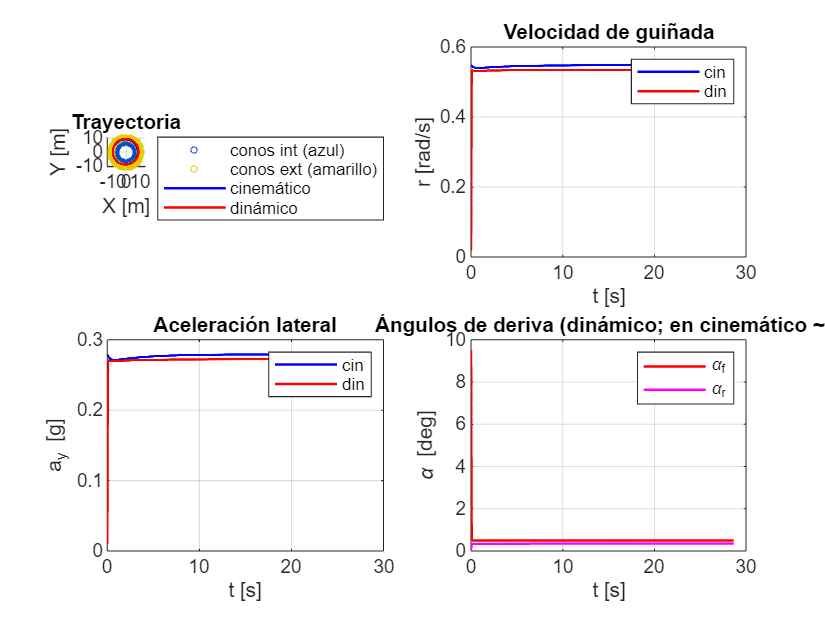

figure('Name','L2 · Skidpad','Color','w');

subplot(2,2,1); hold on; axis equal; grid on;  
  th = linspace(0,2*pi,200);
  plot(geom.R_in*cos(th), geom.R_in*sin(th), 'o','Color',[0 .3 .8],'MarkerSize',3);
  plot(geom.R_out*cos(th),geom.R_out*sin(th),'o','Color',[.9 .8 0],'MarkerSize',3);
  plot(histCin.X, histCin.Y, 'b-','LineWidth',1.2);
  plot(histDin.X, histDin.Y, 'r-','LineWidth',1.2);
  legend('conos int (azul)','conos ext (amarillo)','cinemático','dinámico','Location','bestoutside');
  title('Trayectoria'); xlabel('X [m]'); ylabel('Y [m]');

subplot(2,2,2);   
  plot(histCin.t,histCin.r,'b', histDin.t,histDin.r,'r','LineWidth',1.2);
  ylabel('r [rad/s]'); xlabel('t [s]'); grid on; legend('cin','din');
  title('Velocidad de guiñada');

subplot(2,2,3);   
  plot(histCin.t, histCin.vx.*histCin.r/9.81,'b', ...
       histDin.t, histDin.vx.*histDin.r/9.81,'r','LineWidth',1.2);
  ylabel('a_y [g]'); xlabel('t [s]'); grid on; legend('cin','din');
  title('Aceleración lateral');

subplot(2,2,4);   
  plot(histDin.t, histDin.af*180/pi,'r', histDin.t, histDin.ar*180/pi,'m','LineWidth',1.2);
  ylabel('\alpha [deg]'); xlabel('t [s]'); grid on; legend('\alpha_f','\alpha_r');
  title('Ángulos de deriva (dinámico; en cinemático ~0)');

Como vemos el modelo cinemático traza un círculo de radio constante al no tener deriva, mientras que el modelo dinámico traza un círculo ligeramente mayor con el mismo ángulo de giro del volante debido al subviraje del vehículo. Ambos experimentan una fuerza lateral de aproximadamente 0.55g. 

⚡ En Formula Student, el tiempo en el skidpad mide la aceleración lateral máxima del monoplaza. En la industria del automóvil, los ensayos de radio constante sirven además para medir el **gradiente de subviraje**.

*¿Cuál es la velocidad máxima a la que podemos recorrer el circuito sin salirnos del carril? *

*¿Qué pasaría si definimos un coeficiente de rozamiento mayor en el eje delantero?*

*¿Que pasaría si el coche fuera sobrevirador?*